    ***RESOLUCION DE ECUACIONES:***

***METODO DE EULER:***

f = @(t,y) 1+y/t +(y/t)^2;
a=1; b=3; 
ya= 0 ;% condicion inicial
M = 10 ;% # sub intervalos

E = euler (f, a, b, ya, M)

E =     1.0000         0
    1.2000    0.2000
    1.4000    0.4389
    1.6000    0.7212
    1.8000    1.0520
    2.0000    1.4373
    2.2000    1.8843
    2.4000    2.4023
    2.6000    3.0028
    2.8000    3.7006


Esta tabla se lee:

Columna izquierta los Ti

Colomna derecha los Wi (aproximacion yi)

Primer valor es (to,yo) = (1,0)

Segundo valor es (t1,y1)= (1.2,0.2)

asi, hasta el ultimo 

% se sabe que esta es la solucion
 j = @(t) t*tan(log(t))

j = function_handle with value:
    @(t)t*tan(log(t))


 fplot(j,[1 3]) % Esta es la solucion dada

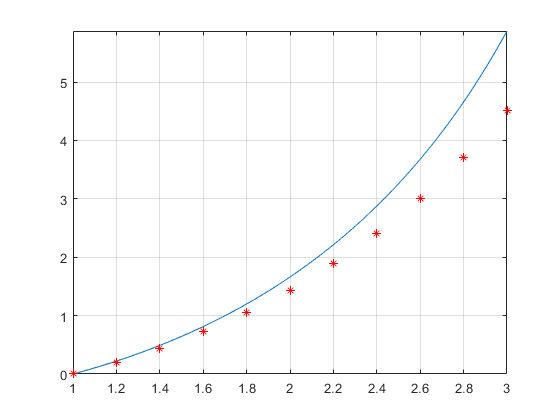

 hold on
 grid on
 plot(E(:,1),E(:,2),"r*")

 hold off
 

Esto es lo que sucede con 10 aproximaciones. Si hacemos lo mismo, pero con mas...

Si se desea calcular el error, ya que tenemos la solucion real entonces...

 j(3)- E(end,2) % Error cometido

ans = 1.3598

 (j(3)-E(end,2))/j(3) % Error relativo

ans = 0.2315

***Metodo de Taylor***

Esta funcion está programada para trabajar con taylor 4. En este ejemplo se pide el calculo de taylor 2.

Las componentes del vector df son:

Componente 1: La ecuaciones diferencial escrita como funcion de f(t,y) 

Componente 2: La primera derivada de la fn del componente 1

Componente 3: Tercer derivada

Componente 4: Cuarta derivada

 % Defina la funcion anonima a trabajar.
 
 % Taylor de orden 2.
 
 df = @(t,y) [-5*y+5*t^2+2*t,2+25*y-10*t^2,0,0] 

df = function_handle with value:
    @(t,y)[-5*y+5*t^2+2*t,2+25*y-10*t^2,0,0]


a= 0; b=1; ya=1/3; M=10

M = 10

 T4 = taylor (df, a, b, ya, M)

T4 =          0    0.3333
    0.1000    0.2183
    0.2000    0.1710
    0.3000    0.1748
    0.4000    0.2198
    0.5000    0.2994
    0.6000    0.4096
    0.7000    0.5480
    0.8000    0.7130
    0.9000    0.9036


 % Defina la funcion anonima a trabajar.
 
 % Taylor de orden 3.
 
 df = @(t,y) [-5*y+5*t^2+2*t,2+25*y-10*t^2,-125*y+50*t^2+30*t,0] 

df = function_handle with value:
    @(t,y)[-5*y+5*t^2+2*t,2+25*y-10*t^2,-125*y+50*t^2+30*t,0]


a= 0; b=1; ya=1/3; M=10

M = 10

 T4 = taylor (df, a, b, ya, M)

T4 =          0    0.3333
    0.1000    0.2114
    0.2000    0.1628
    0.3000    0.1677
    0.4000    0.2141
    0.5000    0.2947
    0.6000    0.4051
    0.7000    0.5428
    0.8000    0.7060
    0.9000    0.8939


***METODO DEL PUNTO MEDIO:***

 f = @(t,y) 1+y/t+(y/t)^2

f = function_handle with value:
    @(t,y)1+y/t+(y/t)^2


 a= 1

a = 1

 b= 4.7

b = 4.7000

 M=37 % numero intervalos

M = 37

 ya = 0 % Condicion inicial

ya = 0

P = puntomedio (f, a, b, ya, M)

P =     1.0000         0
    1.1000    0.1050
    1.2000    0.2209
    1.3000    0.3485
    1.4000    0.4887
    1.5000    0.6425
    1.6000    0.8110
    1.7000    0.9952
    1.8000    1.1964
    1.9000    1.4163


***Rugi-Kutann de orden 4 (rutinas lo llaman heun)***

Con el mismo ejemplo anterior...

H = heun (f, a, b, ya, M)

H =     1.0000         0
    1.1000    0.1052
    1.2000    0.2212
    1.3000    0.3491
    1.4000    0.4897
    1.5000    0.6438
    1.6000    0.8127
    1.7000    0.9974
    1.8000    1.1994
    1.9000    1.4200


***Euler modificado:***

EM = eulerMod (f, a, b, ya, M)

EM =     1.0000         0
    1.1000    0.1050
    1.2000    0.2208
    1.3000    0.3483
    1.4000    0.4885
    1.5000    0.6421
    1.6000    0.8104
    1.7000    0.9944
    1.8000    1.1955
    1.9000    1.4152


***Runge-Kutta 4***

 R = rk4 (f, a, b, ya, M)

R =     1.0000         0
    1.1000    0.1052
    1.2000    0.2212
    1.3000    0.3491
    1.4000    0.4897
    1.5000    0.6439
    1.6000    0.8128
    1.7000    0.9975
    1.8000    1.1994
    1.9000    1.4201


# ***Sistemas de ecuaciones diferenciales:***

***Rugen-Kutta orden 4:***

% Entrada   - F funcion vectorial creada con @
%           - a y b los extremos del intervalo
%           - Za = [x1(a), ... , xn(a)] las condiciones iniciales
%           - M es el numero de pasos (el h)
% Salida    - T es el vector de pasos
%           - Z = [x1(t), ... , xn(t)] donde  xk(t)  es la aproximacion a la
%             k-esima variable dependiente

F = @(t,U) [U(2)-U(3)+t, 3*t^2+2*abs(U(1)), U(2)+exp(-t)]

F = function_handle with value:
    @(t,U)[U(2)-U(3)+t,3*t^2+2*abs(U(1)),U(2)+exp(-t)]


Za = [1.4,1.5,-0.6] % Condicion inicial

Za =     1.4000    1.5000   -0.6000


a = 0.2

a = 0.2000

b = 1

b = 1

M = 4 % Numero sub intervalos

M = 4


[T, Z] = rks4 (F, a, b, Za, M)

T =     0.2000    0.4000    0.6000    0.8000    1.0000


Z =     1.4000    1.5000   -0.6000
    1.8971    2.2128   -0.0848
    2.4902    3.2385    0.5758
    3.2144    4.6705    1.4586
    4.1080    6.6167    2.6591


La matriz T tiene los t_i de cada intervalo

La matriz Z tiene en su primer columna los valores de U1, luego U2 sda columna y asi

 ***Para verlo de manera amigable...***

[T',Z] % En 0.2 tiene imagenes u1= 1.4, u2 =1.5 y u3 = -0.6

ans =     0.2000    1.4000    1.5000   -0.6000
    0.4000    1.8971    2.2128   -0.0848
    0.6000    2.4902    3.2385    0.5758
    0.8000    3.2144    4.6705    1.4586
    1.0000    4.1080    6.6167    2.6591


***Euler vectorial  (Para ec diferenciales vectoriales)***

F = @(t,U) [U(2)-U(3)+t, 3*t^2+2*abs(U(1)), U(2)+exp(-t)]

F = function_handle with value:
    @(t,U)[U(2)-U(3)+t,3*t^2+2*abs(U(1)),U(2)+exp(-t)]


Za = [1.4,1.5,-0.6] % Condicion inicial

Za =     1.4000    1.5000   -0.6000


a = 0.2

a = 0.2000

b = 1

b = 1

M = 4 % Numero sub intervalos

M = 4


[T, Z] = EulerVectorial (F, a, b, Za, M)

T =     0.2000    0.4000    0.6000    0.8000    1.0000


Z =     1.4000    1.5000   -0.6000
    1.8600    2.0840   -0.1363
    2.3841    2.9240    0.4146
    3.0059    4.0936    1.1092
    3.7628    5.6800    2.0178


[T',Z] 

ans =     0.2000    1.4000    1.5000   -0.6000
    0.4000    1.8600    2.0840   -0.1363
    0.6000    2.3841    2.9240    0.4146
    0.8000    3.0059    4.0936    1.1092
    1.0000    3.7628    5.6800    2.0178


***PUNTO MEDIO (VECTORIAL)***

%[T, Z] = PuntoMedioVectorial (F, a, b, Za, M)

F = @(t,u) [u(2),u(3),exp(t)-2*cos(t)*u(3)+u(2)+2*sin(t)*u(1)];
a = 1;
b= 3;
Za = [1 2 0];
M = 3;
[T, Z] = PuntoMedioVectorial (F, a, b, Za, M)

T =     1.0000    1.6667    2.3333    3.0000


Z =     1.0000    2.0000         0
    2.3333    3.4225    5.3531
    5.8046   10.1883   23.5935
   17.8398   39.5818  103.1137


[T',Z] % Primer columna t_i.

ans =     1.0000    1.0000    2.0000         0
    1.6667    2.3333    3.4225    5.3531
    2.3333    5.8046   10.1883   23.5935
    3.0000   17.8398   39.5818  103.1137



% Tercer columna X cuarta fila es U(2) en el punto(3)

***METODO DEL DISPARO:***

F = @(t,u) [u(2) sin(t)+u(1)*exp(t)*sqrt(t^2+1)+u(2)*cos(t)]

F = function_handle with value:
    @(t,u)[u(2),sin(t)+u(1)*exp(t)*sqrt(t^2+1)+u(2)*cos(t)]


G = @(t,u) [u(2) u(1)*exp(t)*sqrt(t^2+1)+u(2)*cos(t)]

G = function_handle with value:
    @(t,u)[u(2),u(1)*exp(t)*sqrt(t^2+1)+u(2)*cos(t)]


Fa = [1 0] % Condicion inicial f

Fa =      1     0


Ga = [0 1] % Condicion inicial g

Ga =      0     1


[T, D1] = PuntoMedioVectorial (F, 0, 1, Fa, 4)

T =          0    0.2500    0.5000    0.7500    1.0000


D1 =     1.0000         0
    1.0313    0.3477
    1.1791    0.9943
    1.5378    2.1494
    2.2728    4.2519


[T',D1]

[T1, D2] = PuntoMedioVectorial (G, 0, 1, Ga, 4)

T1 =          0    0.2500    0.5000    0.7500    1.0000


D2 =          0    1.0000
    0.2813    1.3147
    0.6614    1.8416
    1.2104    2.7778
    2.0684    4.5691


[T1',D2]

ans =          0         0    1.0000
    0.2500    0.2813    1.3147
    0.5000    0.6614    1.8416
    0.7500    1.2104    2.7778
    1.0000    2.0684    4.5691


% Si w es el vector de la solucion para los nodos internos
w=D1(:,1)+(-D1(end,1)/D2(end,1))*D2(:,1)

w =     1.0000
    0.7222
    0.4524
    0.2079
         0


% L = linsht (F1, F2, a, b, alpha, beta, M)
% Para este ejemplo...
a=0

a = 0

b=1

b = 1

M=4

M = 4

alpha= 1

alpha = 1

beta=  0

beta = 0

L = linsht (F, G, a, b, alpha, beta, M)

L =          0    1.0000
    0.2500    0.7226
    0.5000    0.4538
    0.7500    0.2098
    1.0000         0


# Diferencias divididas:

% F = findiff (p, q, r, a, b, alpha, beta, N)
% P acompaña a primera derivada
% Q acompaña a la y(x) la x con la fn p
% R es la fn intependiente solita
% N es el numero sub intervalor 
% intervalo [a,b]
% alpha condicion inicial (resultado)
% beta condicion final (resultado)

r= @(t) sin(t)

r = function_handle with value:
    @(t)sin(t)


q= @(t) exp(t).*sqrt(t.^2+1)

q = function_handle with value:
    @(t)exp(t).*sqrt(t.^2+1)


p = @(t) cos(t)

p = function_handle with value:
    @(t)cos(t)


a=0

a = 0

b=1

b = 1

aplha=1

aplha = 1

beta =0

beta = 0

N =4

N = 4

F = findiff (p, q, r, a, b, alpha, beta, N)

F =          0    1.0000
    0.2500    0.7216
    0.5000    0.4520
    0.7500    0.2082
    1.0000         0
